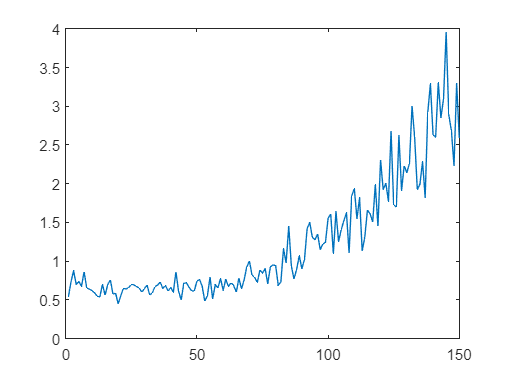

clear;
clc;


BlurTest = importdata("BlurTest.csv");
BlurTestBinary = importdata("BlurTest_binary.csv");
BlurTestAvg = zeros(1,150);
BlurTestElbow = zeros(1,150);
for i = 1:150
    BlurTestAvg(i) = mean(BlurTest(i,:));
end
plot(BlurTestAvg*100)

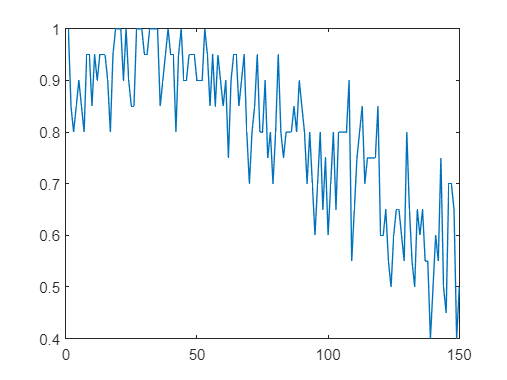

for i = 1:150
    BlurTestElbow(i) = sum(BlurTestBinary(i,:)) / 20;
end
plot(BlurTestElbow)

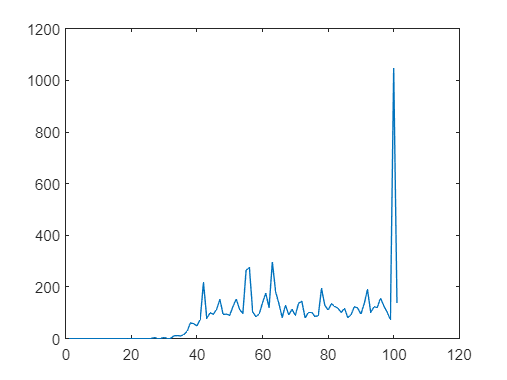




SPTest = importdata("SPTest.csv");
SPTestBinary = importdata("SPTest_binary.csv");
SPTestAvg = zeros(1,101);
SPTestElbow = zeros(1,101);
for i = 1:101
    SPTestAvg(i) = mean(SPTest(i,:));
end
plot(SPTestAvg*100)

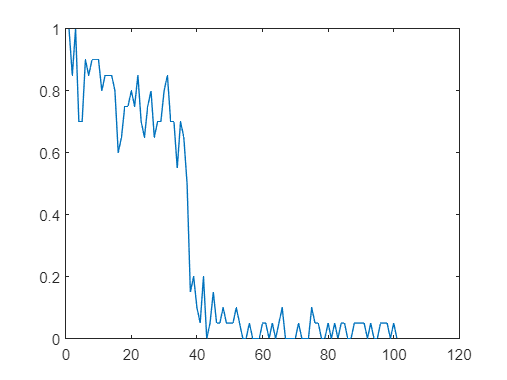

for i = 1:101
    SPTestElbow(i) = sum(SPTestBinary(i,:)) / 20;
end
plot(SPTestElbow)




BlurSPTest = importdata("BlurSPTest.csv");
BlurSPTestBinary = importdata("BlurSPTest_binary.csv");
BlurSPTestAvg = zeros(1,51);
BlurSPTestElbow = zeros(1,51);
for i = 1:51
    BlurSPTestAvg(i) = mean(BlurSPTest(i,:));
end
x = linspace(0,100,51)

x =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98


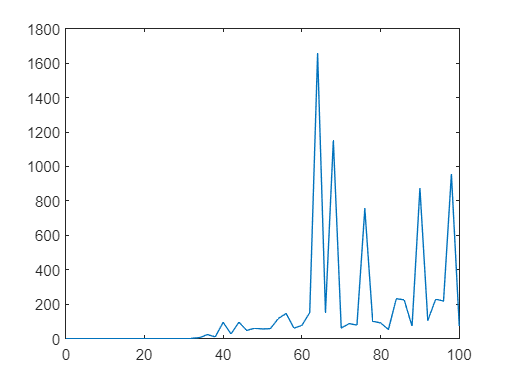

plot(x, BlurSPTestAvg*100)

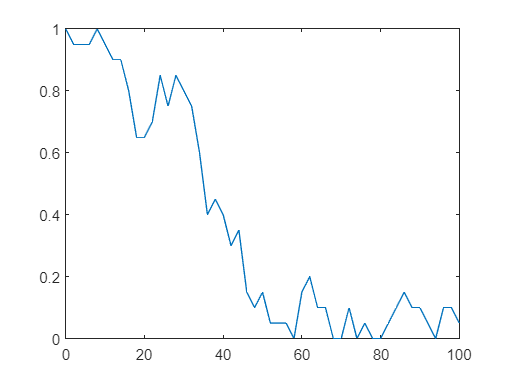

for i = 1:51
    BlurSPTestElbow(i) = sum(BlurSPTestBinary(i,:)) / 20;
end
plot(x, BlurSPTestElbow)








%boxplot([NoNoise*100, G_10*100, G_20*100, G_40*100, G_80*100, G_160*100, G_200*100])


